snr1=1:5:100;
snr1=10*log10(snr1)

snr1 =                    0   7.781512503836437  10.413926851582250  12.041199826559248  13.222192947339193  14.149733479708180  14.913616938342727  15.563025007672874  16.127838567197355  16.627578316815740  17.075701760979364  17.481880270062003  17.853298350107671  18.195439355418689  18.512583487190753  18.808135922807914  19.084850188786497  19.344984512435676  19.590413923210935  19.822712330395685


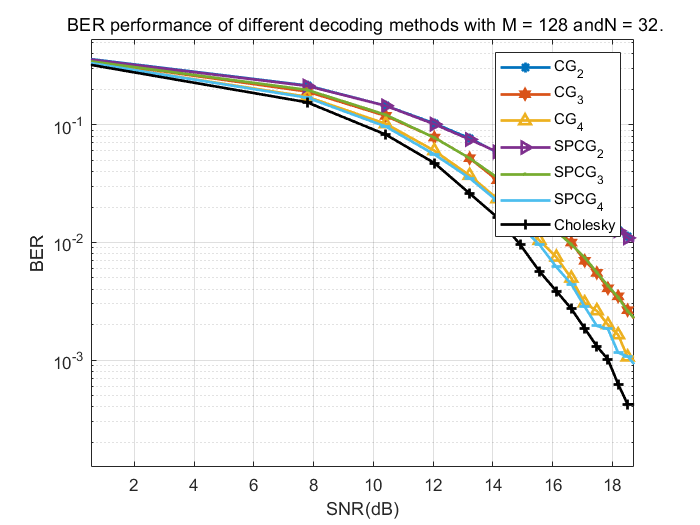

semilogy(snr1,CG_2_32/1000,"LineWidth",1.6,"Marker","*")%,"Color",'g');
xlabel('SNR(dB)')
ylabel("BER")
hold on;
grid ON
semilogy(snr1,CG_3_32/1000,"LineWidth",1.6,"Marker","hexagram")%,"Color",'g');
semilogy(snr1,CG_4_32/1000,"LineWidth",1.6,"Marker","^")%,"Color",'g');
semilogy(snr1,SPCG_2_32/1000,"LineWidth",1.6,"Marker",">")%,"Color",'g');
semilogy(snr1,SPCG_3_32/1000,"LineWidth",1.6,"Marker",".")%,"Color",'g');
semilogy(snr1,SPCG_4_32/1000,"LineWidth",1.6,"Marker","_")%,"Color",'g');
semilogy(snr1,INV_32/1000,"LineWidth",1.6,"Marker","+","Color",'K');
legend("CG_2","CG_3","CG_4","SPCG_2","SPCG_3","SPCG_4","Cholesky")
title(" BER performance of different decoding methods with M = 128 andN = 32.")